# EFMouse: 4x1 montage

EFMouse is a Matlab tool for electric field modelling in the mouse brain.

This notebook reproduces results for the 4x1 montage in Sanchez-Romero et al., (2024).

The notebook is also an introductory tutorial to simulate other montages.

*(Developed by Ruben Sanchez-Romero and Bart Krekelberg,*

*Rutgers-Newark, Center for Molecular and Behavioral Neuroscience,*

*for support email: ruben.saro@rutgers.edu)*

## Introduction

EFMouse combines several elements from previous work: 

- Anatomical data from the Digimouse project.

- A refined finite element mesh of the Digimouse by Alekseichuk et al., (2019), *Neuroimage*. 

- Matlab code and inspiration from the ROAST toolbox.

- The getDP finite element method (FEM) solver (v 3.2.0).

- The Allen mouse brain atlas.

Key new functionality includes: 

- Positioning electrodes in arbitrary locations on the mouse body.

- Modeling craniotomies in the mouse skull.

- Analyzing the electric field in user-defined regions of interest

- Analyzing the electric field in brain regions defined in the Allen mouse atlas.

- A measure of relative focality of the electric field.

- A measure of direction homogeneity of the electric field.

For details see Sanchez-Romero et al., (2024) and *EFMouse.m* Matlab code.

## Typical workflow

The typical workflow to generate a model consists of several stages

- stage 0 : Initialize. 

- stage 1: Define elecrodes and (optionally) a craniotomy.

- stage 2: Impose boundary conditions.

- stage 3: Export files for the FEM solver getDP.

- stage 4: Run the FEM solver.

- stage 5: Map the results to the Allen mouse atlas.

### Stage 0: Initialize

We start by setting up the basic parameters of the `EFMouse` object:

o = EFMouse; % Create a default empty object of the class EFMouse
o.dir = '/Users/rubensanchez/desktop/EFMouse/4x1Montage'; % Results and the object (4x1.mat) will be saved here.
o.ID = '4x1';  % A name/tag for this simulation.
o.log  = true;  % Create a log file.

Note: The log file is created but doesn't update when running a simulation from a notebook (like here). It will properly update when running directly from the Matlab command line.

`initialize()` creates the folder to store the results. With `overwrite=true`, anything in this folder will be deleted.

o.initialize(overwrite=true); 

The initialized `EFMouse` object contains the default mouse mesh (without stimulation electrodes). Let's visualize it.

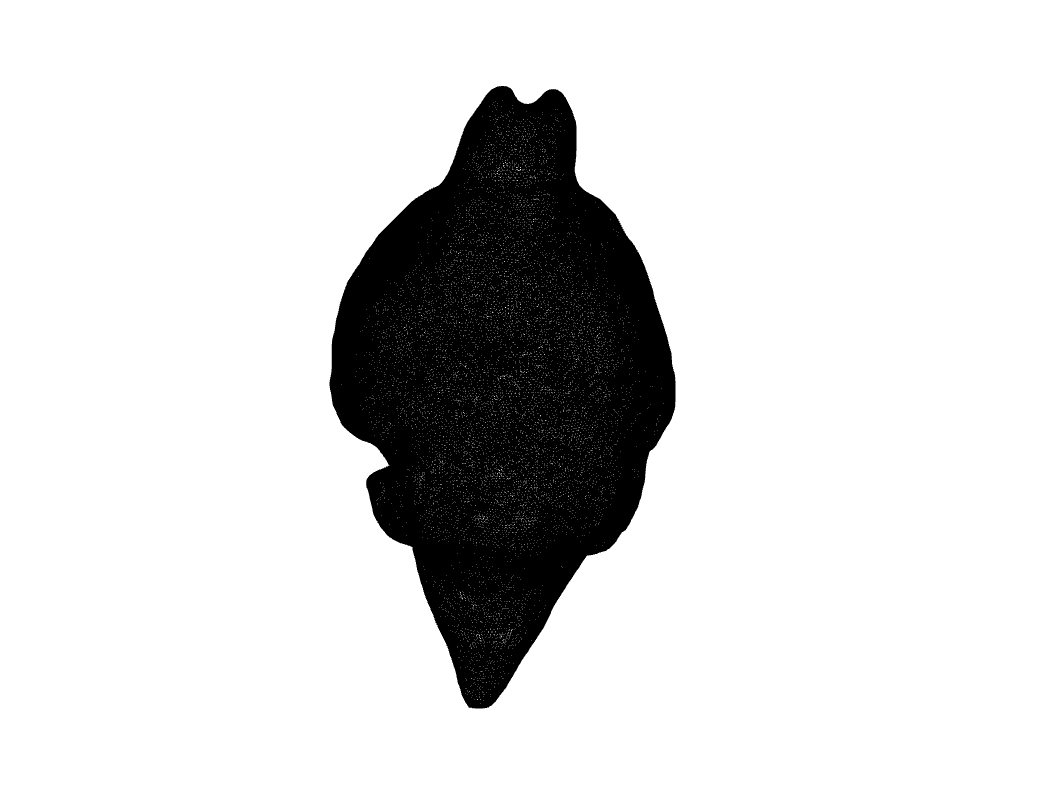

plotMesh(o)

The mesh is pretty dense, so it will look like a black blob. The olfactory bulbs are visible on the top. In a regular figure window, you can use the Matlab figure tools to rotate or zoom. (You can also adapt the `plotMesh()` function in *EFMouse.m* to modifiy the figure directly.)

### Stage 1: Create electrodes and a craniotomy

Now we define a 4x1 stimulation montage: 4 electrodes on the head (targeting visual areas), with a return electrode on the lumbar area.  

o.eTag = ["Anterior" "Posterior" "Lateral" "Medial" "Lumbar"];
% currents need to sum to 0. (In milliamps (mA) units.)
o.eCurrent = [0.05,0.05,0.05,0.05,-0.2];
% center coordinate of the electrode position (in mesh space) 
o.eCenter = [-3.56,29.5,5.45;
             -3.43,24.8,6.02;
             -5.5,26.72,3.58; 
              -1.2,27.11,6.29;
              -1.1819,-9.655,10.129]';
% radius of the electrodes (in mesh space units) (1 mesh unit ~ 1 mm)
o.eRadius = [0.71,0.67,0.64,0.6,0.8]

Add a craniotomy:

% center coordinate of the craniotomy position (in mesh space)
o.cCenter = [-3.4236,27.1067,5]';

o = EF Mouse Model (label: 4x1) in directory /Users/rubensanchez/desktop/EFmouse/4x1Montage (stage=0).

% radius of the creaniotomy (in mesh space units) (1 mesh unit ~ 1 mm)
o.cRadius = 1.5;

To add these to the model, we run the pipeline to stage 1. With `show=true`, this also opens a figure for inspection of the mesh:

o.run(targetStage=1,show=true)

This mesh now shows the electrodes in red and blue (the blue return is out of the field of view; on the lumbar area), for the craniotomy, skin removal is shown in green and skull removal shown in yellow.

### Stage 2: Find the electrode boundaries and add to the mesh

In this stage, EFMouse searches for the edges of the electrodes as this is where the current flows into the model. The boundary conditions of the Laplace equation are set here. 

o.run(targetStage=2)

### Stage 3: export the mesh and model

Up until this stage, all changes were internal to the Matlab object (saved in *4x1.mat*), now we export files that the FEM solver getDP can read. The *.msh* file contains information on the mesh (all the nodes, elements, labels and boundaries), and the *.pro* file tells getDP which partial differential equations (PDE) model it needs to solve this mesh.

Compute stage 1 - computeMesh
EF Mouse Model (label: 4x1) in directory /Users/rubensanchez/desktop/EFmouse/4x1Montage (stage=0).
-Creating craniotomy-
 Craniotomy: touching tissue:
   gray: num elements = 6884
   csf: num elements = 6083
   bone: num elements = 8247
   skin: num elements = 1551
 Craniotomy only removes skin and bone.
-Creating 5 electrodes-
 Electrode: Anterior: touching tissue:
   skin: num elements = 39
   Creating electrode Anterior in max touched tissue: skin.
 Electrode: Posterior: touching tissue:
   skin: num elements = 46
   Creating electrode Posterior in max touched tissue: skin.
 Electrode: Lateral: touching tissue:
   skin: num elements = 125
   Creating electrode Lateral in max touched tissue: skin.
 Electrode: Medial: touching tissue:
   skin: num elements = 110
   Creating electrode Medial in max touched tissue: skin.
 Electrode: Lumbar: touching tissue:
   skin: num elements = 45
   Creating electrode Lumbar in max touched tissue: skin.


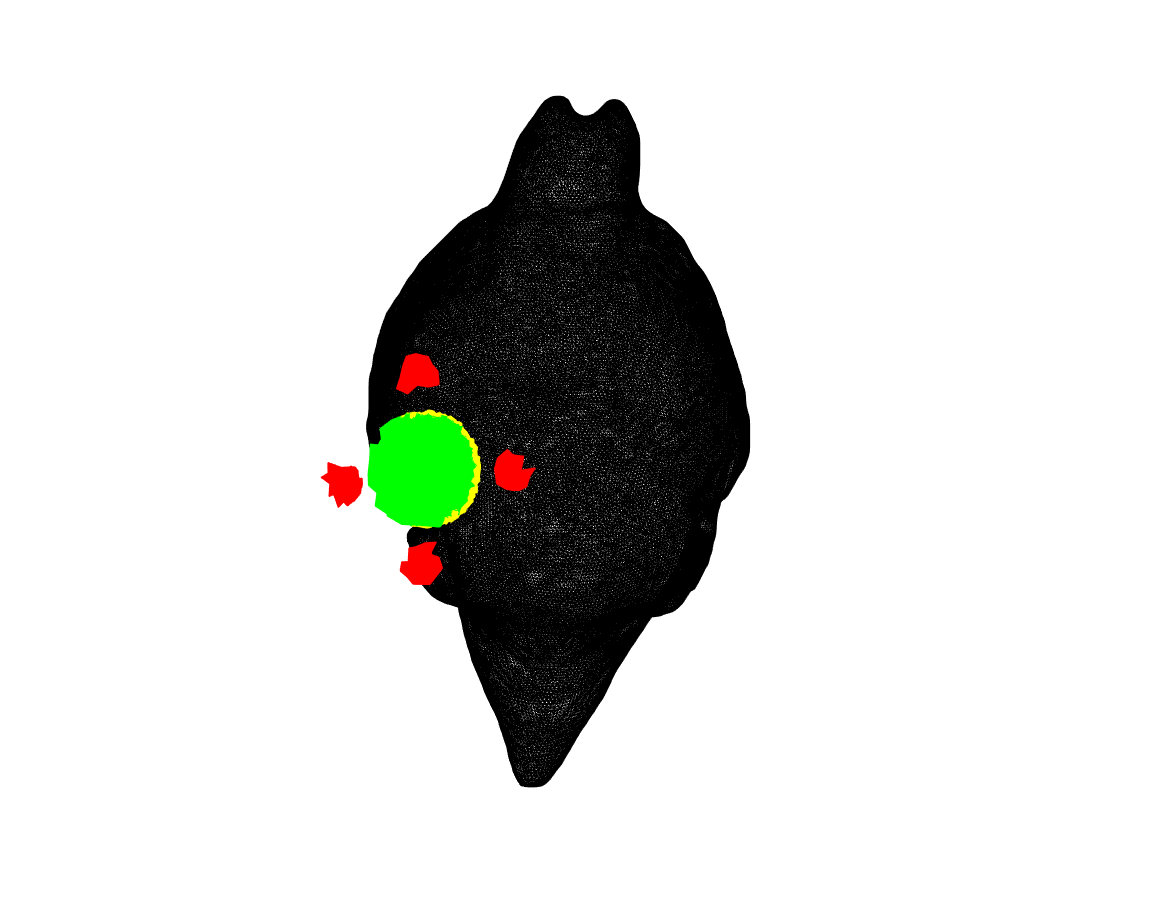

Stage 1 complete - 56.9547 seconds 


o.run(targetStage=3)

For troubleshooting, have a look at the *.pro* file in the project folder; it contains all the model specifications, including conductivity (in siemens per meter S/m) for the different tissues/elements.

type(file(o,"PRO"))

This file can be opened in the getDP gui to run it manually, but stage 4 runs it for you.

### Stage 4: run getDP

It will take getDP between 15 and 30 minutes to compute the solutions of the Laplace equation (on 2024 Mac or Windows hardware). The results are saved in *_e.pos* and *_v.pos* files (in getDP format). In the object the results are saved as .field and .voltage.

o.run(targetStage=4,show=false);

Compute stage 2 - computeBoundary
                 Electrode Area
                 ______________

    Anterior        0.78309    
    Posterior       0.67532    
    Lateral         0.59597    
    Medial          0.62975    
    Lumbar           1.0771    

Stage 2 complete - 92.0351 seconds 


Use the `plotEf()` function to visualize the electric field in the X direction, and then the electric field magnitude.

plotEf(o,type='eX',percentile=98, tissue='gray');

Compute stage 3 - export data
----Starting saveMesh...01-Jul-2024 15:14:19
----saveMesh elapsed time: 32.8658 seconds

----Starting savePro...01-Jul-2024 15:14:52
----savePro elapsed time: 0.2226 seconds

Stage 3 complete - 51.0340 seconds 


plotEf(o,type='eMag',percentile=98,tissue='gray')

### **Tissue Based Analysis**

In general, we focus on the brain, but if necessary, we can compute electric field estimates for the rest of the mouse body for a full characterization of the anatomical effects of the electrical stimulation protocol. See Sanchez-Romero et al., (2024) for a full description of the electric field metrics.

analyzeTissue(o)

/* 
 .pro file created by EFmouse on 01-Jul-2024 15:14:52 
 ID: 4x1 
 Dir: /Users/rubensanchez/desktop/EFmouse/4x1Montage 
 */

Group {

gray = Region[1];
csf = Region[2];
bone = Region[3];
skin = Region[4];
eye = Region[5];
craniotomy = Region[6];
skinremoved = Region[7];
Anterior = Region[8];
Posterior = Region[9];
Lateral = Region[10];
Medial = Region[11];
Lumbar = Region[12];
boundaryAnterior = Region[13];
boundaryPosterior = Region[14];
boundaryLateral = Region[15];
boundaryMedial = Region[16];
boundaryLumbar = Region[17];
DomainC = Region[{gray,csf,bone,skin,eye,craniotomy,skinremoved,Anterior,Posterior,Lateral,Medial,Lumbar}];
AllDomain = Region[{gray,csf,bone,skin,eye,craniotomy,skinremoved,Anterior,Posterior,Lateral,Medial,Lumbar,boundaryAnterior,boundaryPosterior,boundaryLateral,boundaryMedial,boundaryLumbar}];
}

Function {

sigma[gray] = 0.275;
sigma[csf] = 1.654;
sigma[bone] = 0.01;
sigma[skin] = 0.465;
sigma[eye] = 0.5;
sigma[craniotomy] = 1.654;
sigma[skinremoved] = 2.5e

### ROI Analysis

Now that we have the field estimates for each node in the mesh, we can do an ROI based analysis. For instance, a box ROI.

For the relative focality the reference area is the rest of the gray tissue. 

roi.shape = 'box';

Compute stage 4 - computeField
Info    : Running '/Users/rubensanchez/Desktop/roast/EFmouse_class/efMouseMod/lib/getdp-3.2.0/bin/getdpMac /Users/rubensanchez/desktop/EFmouse/4x1Montage/4x1.pro -solve EleSta_v -msh /Users/rubensanchez/desktop/EFmouse/4x1Montage/4x1.msh -pos Map' [GetDP 3.2.0, 1 node, max. 1 thread]
Info    : Started (Mon Jul  1 15:23:08 2024, Wall = 0.174001s, CPU = 0.028321s, Mem = 5.37891Mb)
Info    : Initializing Gmsh
Error   : Unknown number option 'General.NativeFileChooser'
Info    : Loading problem definition '/Users/rubensanchez/desktop/EFmouse/4x1Montage/4x1.pro'
Info    : Selected Resolution 'EleSta_v'
Info    : Loading Geometric data '/Users/rubensanchez/desktop/EFmouse/4x1Montage/4x1.msh'
Info    : System 'Sys_Ele' : Real
P r e - P r o c e s s i n g . . .
Info    : Treatment Formulation 'Electrostatics_v'
  0%    : Pre-processing                                          
 10%    : Pre-processing                                          
 20%

----Starting plotEf...01-Jul-2024 16:54:21


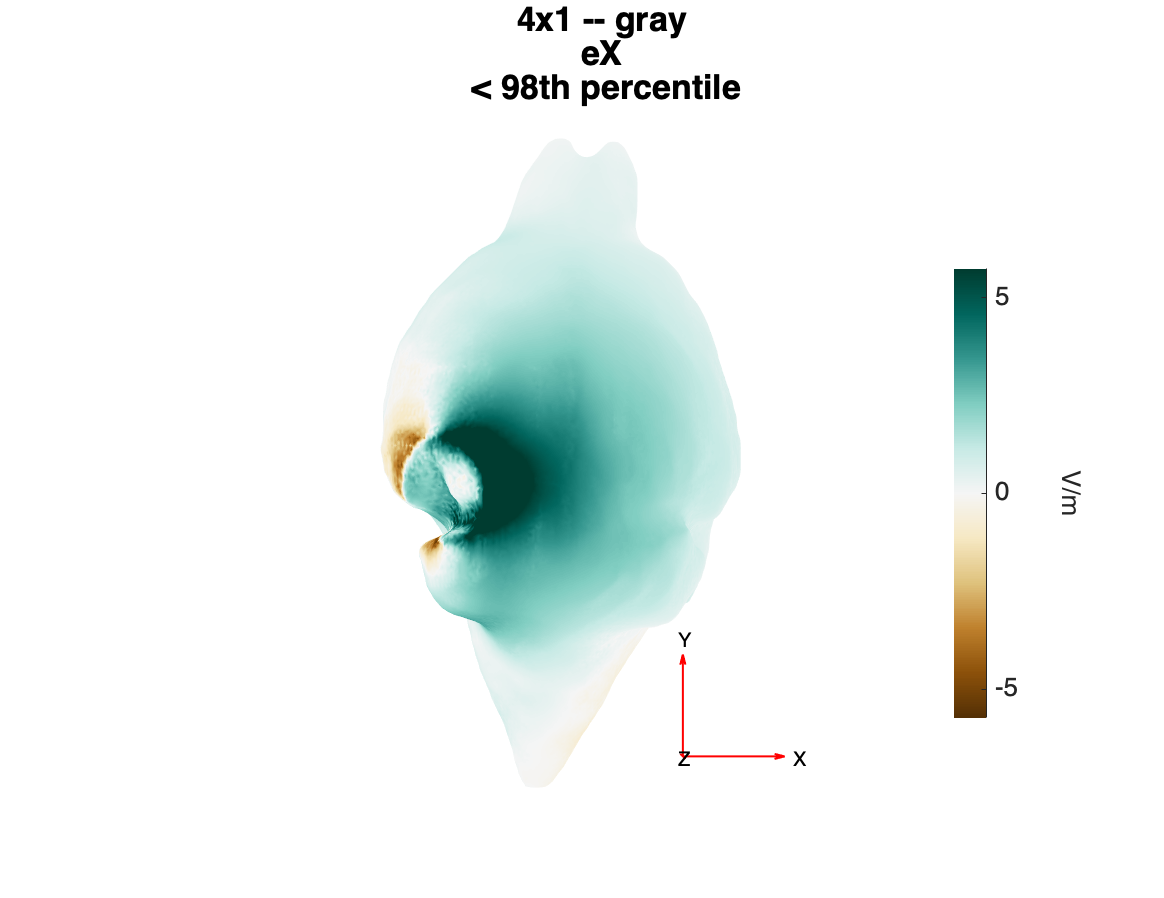

----plotEf elapsed time: 2.6230 seconds


roi.dim = [[-4.0087 -2.56];[26.4022 27.64];[3 4]]';% Define the limits of the box ROI (x,y,z)(in mesh space units) (1 mesh unit ~ 1 mm)
summary = analyzeRoi(o,roi,plot=true,foc_percentile_max=99.9,foc_threshold=75); % Define values for relative focality metric.
% Rotate and zoom to view the (purple) box ROI underneath the craniotomy

----Starting plotEf...01-Jul-2024 16:54:24


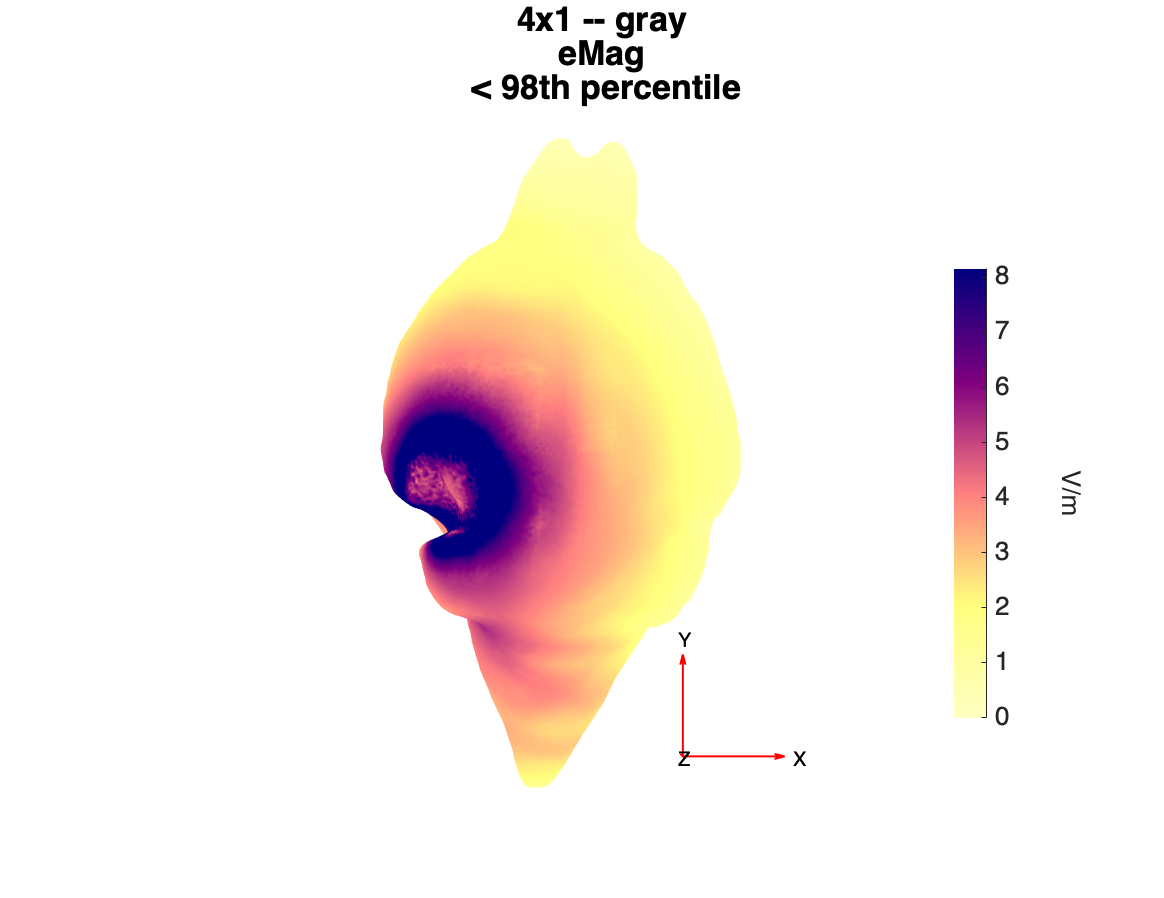

----plotEf elapsed time: 1.8638 seconds


xlim([-3.31 1.13])

ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

For comparison, define an homologous box ROI but in the right hemisphere

roi_control.shape = 'box';

----Starting analyzeTissue...01-Jul-2024 17:00:12
Electric field summary statistics for gray tissue
              mean       median      std        min       max  
            ________    ________    ______    _______    ______

    eX        1.2703     0.99226    1.1544    -5.4246    14.526
    eY      -0.54963    -0.31191    1.5478    -12.784    12.106
    eZ       -1.6616     -1.2725    1.3786    -16.308    2.5609
    eMag      2.6406      2.1451    1.8255    0.21219    18.899

[Homogeneity ranges from 0 to 1]
Homogeneity = 0.8260, for ef_norm_mean: (0.507 -0.159 -0.632)

Electric field summary statistics for csf tissue
             mean       median      std        min       

roi_control.dim = [[2.56 4.0087];[26.4022 27.64];[3 4]]';% Define the limits of the box ROI (in mesh space units)
summary = analyzeRoi(o,roi_control,plot=true,foc_percentile_max=99.9,foc_threshold=75);
% Rotate and zoom to view the (purple) box ROI underneath the craniotomy
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

----Starting analyzeRoi...01-Jul-2024 17:34:56
Electric field summary statistics for a box roi in gray
              mean       median       std        min       max  
            ________    ________    _______    _______    ______

    eX        3.0435      2.8444     1.1362    0.47771    8.5696
    eY      -0.47302    -0.35704    0.95461    -4.2281    1.6231
    eZ       -7.3414     -7.3198     1.2901    -10.475    -3.544
    eMag      8.0868      8.0123     1.3604     4.4533    12.903

Relative focality = 1.0463% of 161805 reference nodes (eMag > 75.00% of the ROI max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9855, for ef_norm_mean: (0.379 -0.061 -0.908)


### Stage 5: Volumetric Analysis

The mesh coordinates are not particularly intuitive, and you may want to estimate electric fields in specific brain areas (as defined in an atlas). EFMouse does this in reference to the Allen Mouse Brain Atlas. 

To use this, we first have to map the mesh-based results to the Allen Atlas. This is Stage 5 of the pipeline. This stage first exports the mesh-based results to a volume (using linear interpolation) and then uses the FLIRT tool in FSL to transform this volume to the coordinates of the Allen Atlas. Note that the alignment between the Digimouse mesh and the Allen Atlas is not perfect because they are based on different imaging modalities (and different mouse strains). (See Sanchez-Romero et al., (2014).) 

This will fail if FSL is not installed.

o.run(targetStage=5,startStage=5)

### Atlas Based Analysis

Once stage 5 has completed we can query electric fields based on a region that is defined in the Allen Atlas. For instance: 'Visual areas' for the left hemisphere.

For the relative focality the reference area is the rest of the Allen atlas "Isocortex".

T = analyzeAtlas(o,"Visual areas",hemisphere="left",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

For comparison, we can query results for the right hemisphere, which is contra-lateral from the targeted area.

T = analyzeAtlas(o,"Visual areas",hemisphere="right",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

## Tips and Tricks

- The run function can be called with any `targetStage` from 0 to 5. Stages that have already been completed will not be run again, and all stages that need to be completed to reach the `targetStage` will be completed in turn.

- IMPORTANT: To continue working with a model from a previous Matlab session, you create an `EFMouse` object with the `dir` and `ID` input arguments to specify the folder with the (previously saved) results and the ID of the montage. For instance, to open the simulation from the tutorial and also know the stage:

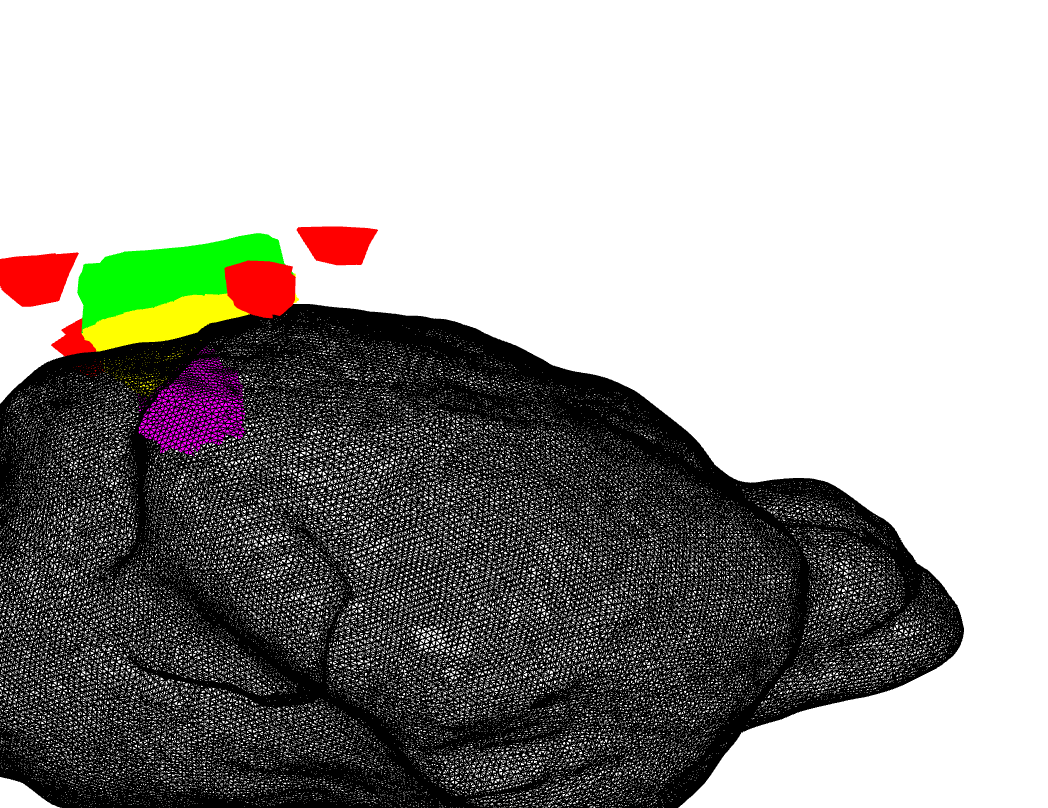

----Starting analyzeRoi...01-Jul-2024 17:35:05
Electric field summary statistics for a box roi in gray
              mean       median       std        min        max   
            ________    ________    _______    _______    ________

    eX        1.2782      1.2861    0.21287    0.70558      1.7305
    eY      -0.76965    -0.72403    0.14409    -1.1859    -0.53497
    eZ       -1.0586     -1.0639    0.11413    -1.3238    -0.73842
    eMag      1.8405      1.8344    0.19583     1.3633      2.2942

Relative focality = 64.3592% of 161865 reference nodes (eMag > 75.00% of the ROI max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9939, for ef_norm_mean: (0.692 -0.418 -0.579)


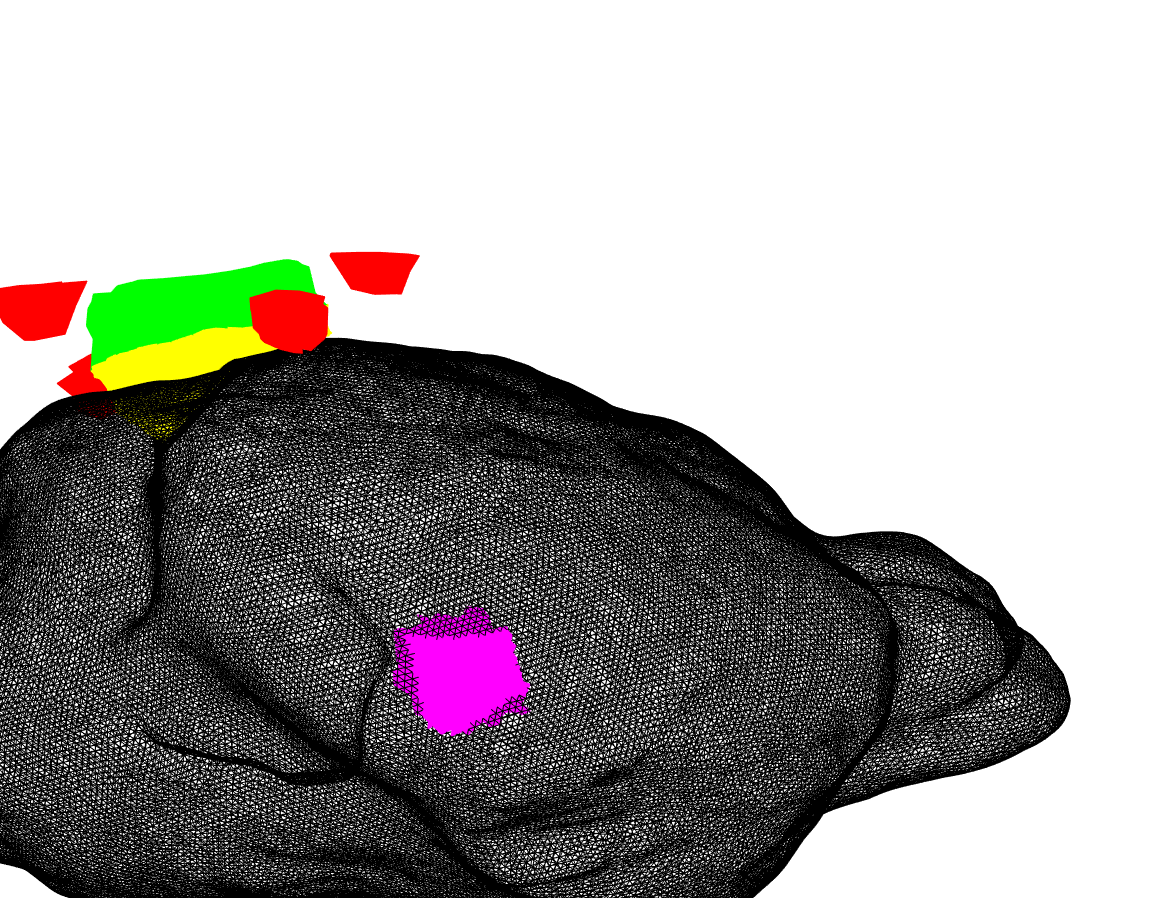

Compute stage 5 - computeVoxelSpace
----Starting computeVoxelSpace...01-Jul-2024 17:18:21
----Exporting to NIFTI volumes 
---/Users/rubensanchez/desktop/EFmouse/4x1Montage/4x1_efm.nii.gz created
---/Users/rubensanchez/desktop/EFmouse/4x1Montage/4x1_efX.nii.gz created
---/Users/rubensanchez/desktop/EFmouse/4x1Montage/4x1_efY.nii.gz created
---/Users/rubensanchez/desktop/EFmouse/4x1Montage/4x1_efZ.nii.gz created
----computeVoxelSpace elapsed time: 26.6836 seconds
Stage 5 complete - 78.0296 seconds 


----Starting analyzeAtlas...01-Jul-2024 17:36:03
Area: Visual areas (1.0% of brain) , hemisphere left 
              mean       median      std        min        max  
            ________    ________    ______    ________    ______

    eX        4.8488       4.937    2.5216      -2.194    12.861
    eY      -0.40598    -0.24019    2.0952     -10.013     7.306
    eZ       -6.3823      -6.751    2.5299     -13.498         0
    eMag       8.575      8.7693    2.8676    0.003294    16.273

Relative focality = 0.1537% of 92410 reference voxels (eMag > 75.00% of the area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9291, for ef_norm_mean: (0.558 -0.049 -0.741)
----analyzeAtlas elapsed time: 0.9462 seconds


----Starting analyzeAtlas...01-Jul-2024 17:36:04
Area: Visual areas (1.0% of brain) , hemisphere right 
              mean       median       std         min         max  
            ________    ________    _______    _________    _______

    eX         1.706      1.8367    0.77312    0.0021152     3.0388
    eY      -0.76484    -0.82405    0.41637      -1.6543    0.14136
    eZ        -1.036     -1.1166    0.46465      -1.7651          0
    eMag       2.168      2.3652    0.92598    0.0025962     3.5464

Relative focality = 37.8771% of 92457 reference voxels (eMag > 75.00% of the area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9855, for ef_norm_mean: (0.782 -0.361 -0.479)
----analyzeAtlas elapsed time: 0.8726 seconds

o = EF Mouse Model (label: 4x1) in directory /Users/rubensanchez/desktop/EFmouse/4x1Montage (stage=5).

o = EFMouse(dir='/Users/rubensanchez/desktop/EFMouse/4x1Montage',ID='4x1')